%6번
clear
t = [-6:0.01:6];
x_t = stepfun(t,-1)-stepfun(t,1);
h_t = (-t+2).*(stepfun(t,0)-stepfun(t,2));
%conv start
m=length(x_t);
n=length(h_t);
X=[x_t,zeros(1,n)];
H=[h_t,zeros(1,m)];
for i=1:n+m-1
    Y(i)=0;
    for j=1:m
        if(i-j+1>0)
            Y(i)=Y(i)+X(j)*H(i-j+1);
        else
        end
    end
end
y_t = Y*0.01

y_t =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


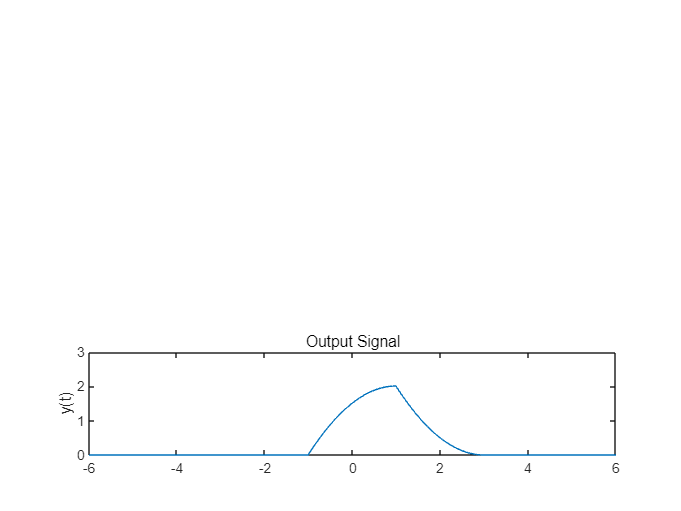

%conv finish
figure;
subplot(3,1,3); plot(t,y_t(601:1801));
axis([-6 6 0 3]);
ylabel('y(t)');
title('Output Signal');